a=[1 -.5 .25]

a =     1.0000   -0.5000    0.2500


b=[1 2 0 1]

b =      1     2     0     1


n=0:100;
h=impz(b,a,n)

h =     1.0000
    2.5000
    1.0000
    0.8750
    0.1875
   -0.1250
   -0.1094
   -0.0234
    0.0156
    0.0137


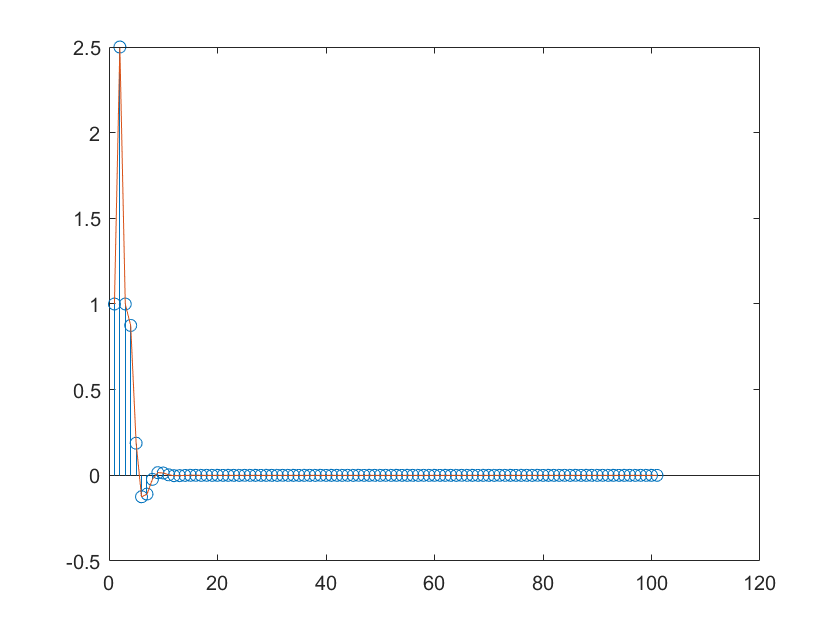

stem(h);hold on
plot(h);

%  check the system stability by cheking the impulse sequense is absolutely
%  summable or not
if (sum(abs(h)))
    disp('System is stable');
else 
    error('System in unstable')
end

System is stable


%  check the system stability by checking the absolutele value of roots of 
% a_n polynomial  is less than 1 or not
if (abs(roots(a))<1)
    disp('System is stable');
else 
    error('System in unstable')
end

System is stable
